# **PCE VS RSM**

**This example is **with known exact solution. Compared with fitting between PCE and RSM

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - COMPUTATIONAL MODEL

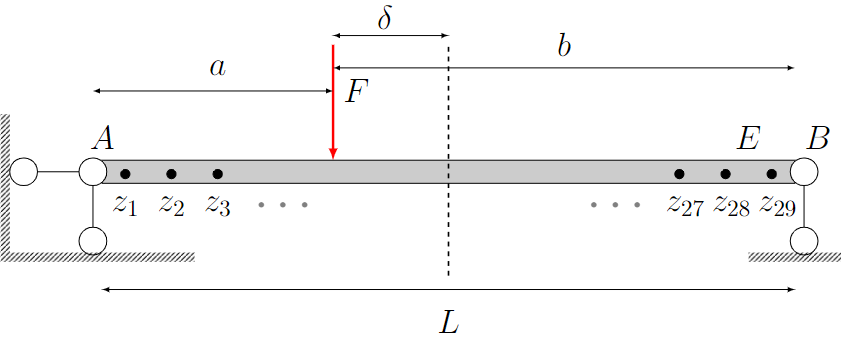

        b_b = 0.15; % beam width  (m)

        b_h = 0.3; % beam height (m)

        a % distance from the point A (m)

        b % distance from the point B (m)

        L = 30; % beam length (m)

        F = 43000;% Concentrated force (N)

**Computational model:**

$a = \frac{L}{2}+ \delta$;$b = \frac{L}{2}- \delta$


$$\mathcal{M}(E,\delta,z) = \frac{F b  z  [(L^2 - b^2) - z^2]}{6LEI} \ \ \   \ \ \ \ \ \ \ z \le a$$
 


$$\mathcal{M}(E,\delta,z)  =  \frac{F b  [\frac{L}{b} (z - a)^3 + (L^2 - b^2)]}{6LEI} \ \ \ \ z> a
$$


Calculate the Mean-square-error  data for  surrogate


$$r(\vec{\theta},\vec{z}) = \frac{1}{N} \sum_{i = 1}^{N}(Y_i - \mathcal{M}(\vec{\theta},\vec{z}))^2$$



$$\vec{\theta} = [E,\delta];\vec{z} = [z_1,z_2,...,z_{28},z_{29}];$$


$r$ is residual; $\vec{x}$ is parameters of interests; $E $ is elastic modulus; $\delta$ is the loading postion

$\vec{z} $is the different measurement points along the beam;

$\mathcal{M}$ is the FE model; $Y_i$ is the measurement data; $N$ is the number of experiment expNum.

Create a MODEL from the function file:

ModelOpts.mFile = 'Analytical_Beam_Solution';

myModel = uq_createModel(ModelOpts);

## 3 - PROBABILISTIC INPUT MODEL

$E \sim \mathcal{u}(19e9,31e9)$; $\delta \sim \mathcal{u}(-10,10)$

% Young's modulus
InputOpts.Marginals(1).Type = 'Uniform';
InputOpts.Marginals(1).Parameters  = [10e9 30e9];
%InputOpts.Marginals(1).Bounds = [10e9 35e9];

% Concentrated load loading position
InputOpts.Marginals(2).Type = 'Uniform';
InputOpts.Marginals(2).Parameters  = [-15 15];
%InputOpts.Marginals(2).Bounds = [-15 15];

myInput = uq_createInput(InputOpts);

## 4 - POLYNOMIAL CHAOS EXPANSION (PCE) METAMODELS $\tilde{\mathcal{M}}(r)$

Calculate the polynomial chaos expansion (PCE) coefficients.

Select PCE as the metamodeling tool in UQLab:

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';

Select the sparse-favouring least-square minimization LARS for the 

PCE coefficients calculation strategy:

metaopts.Method = 'LARS';

Select the PCE options and create the PCE model:

metaopts.Degree = 1:20;

Experimental design

metaopts.ExpDesign.NSamples = 150;
metaopts.ExpDesign.Sampling = 'LHS';

Assign the beam function model as the full computational model of the PCE metamodel:

metaopts.FullModel = myModel;

Calculation

myPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 12 and qNorm 1.00 for output variable 1
Final LOO error estimate: 1.176465e-06
---                 Calculation finished!                               ---


## 5 - Results

Print a summary of the resulting PCE metamodel:

uq_print(myPCE)

%------------ Polynomial chaos output ------------%
   Number of input variables:    2
   Maximal degree:               12
   q-norm:                       1.00
   Size of full basis:           91
   Size of sparse basis:         78
   Full model evaluations:       150
   Leave-one-out error:          3.7794039e-08
   Modified leave-one-out error: 1.1764647e-06
   Mean value:                   1.2002
   Standard deviation:           1.4708
   Coef. of variation:           122.544%
%--------------------------------------------------%


Create a validation sample of size  from the input model:

Xval = uq_getSample(1e4);

Evaluate the full model response at the validation sample points:

Yval = uq_evalModel(myModel,Xval);

Responses for PCE 

YPCE = uq_evalModel(myPCE,Xval);

True vs predicted plot

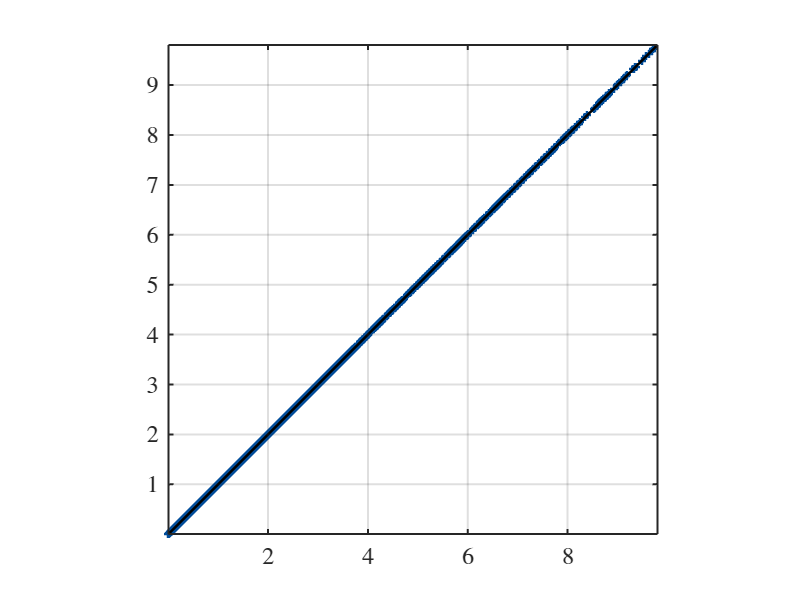

close all;
uq_figure
uq_plot(Yval, YPCE, '+')
hold on
uq_plot([min(Yval) max(Yval)], [min(Yval) max(Yval)], 'k')
hold off
axis equal
axis([min(Yval) max(Yval) min(Yval) max(Yval)])

Export the PCE strucuture

save myPCE

## 6 - Define the priors for E, $\delta$ and discrepancy $\sigma$

By default, UQlab assumes an independent and identically distributed discrepancy

$\varepsilon \sim \mathcal{N}(0,\mu_{y}^2)$, with $\mu_{y} = \frac{1}{N}\sum_{i = 1}^{N}y_i$

synthetic ground truth

$E$ = 25e9;$\delta$ = -3;noise = 0;

Measurement = Deflection(25e9,-3,0);

 priors

%Priors on E and p
PriorOpts.Marginals(1).Name = 'E';               % Young's modulus
PriorOpts.Marginals(1).Type = 'Gaussian';
PriorOpts.Marginals(1).Moments = [25e9 5e9];   % (N/m^2)
PriorOpts.Marginals(1).Bounds = [10e9 35e9];

PriorOpts.Marginals(2).Name = 'delta';               % Concentrated load loading position
PriorOpts.Marginals(2).Type = 'Gaussian';
PriorOpts.Marginals(2).Moments = [0 5]; % (N/m)
PriorOpts.Marginals(2).Bounds = [-10  10];


PriorOpts.Marginals(3).Name = 'sigma2'; % variance
PriorOpts.Marginals(3).Type = 'Uniform';
sigma2 = mean(Measurement(:,:),"all");
PriorOpts.Marginals(3).Parameters = [0 sigma2^2];


myPriorDist = uq_createInput(PriorOpts);

## 7 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$    \log  \mathcal{L} (\mathcal{\Theta }) = \sum_{i=1}^{N}\left(-\frac{1}{2}\left(r_i(\vec{x},\vec{z})\right)^{T} \Sigma(\epsilon)^{-1}\left(r_i(\vec{x},\vec{z})\right)\right) - \frac{3N}{2}\log(2\pi) - \frac{N}{2}\log\left(\det(\Sigma(\epsilon))\right)$$


Monitored data $Y_i$ for beam deflection have been used in PCE surrogate model. No measurements available for Bayesian inference: Pass zeros  to measurement $Y_i$ just for calculation, which equals:

## 
$$r(\vec{x},\vec{z}) \sim (0- r(\vec{x},\vec{z}) ) \sim (Y_i - \mathcal{M}(\vec{x},\vec{z}))}$$


$r(\vec{x},\vec{z})$ dim 248X1 $\sim$ $(Y_i - \mathcal{M}(\vec{x},\vec{z}))}$ dim 248X29

Also, measurement data for $Y_{10 X 29}$ changed into $Y_{10X1}$

y = zeros(1,1);
myData.y = y;
myData.Name = 'Zeros vector measurement for Bayesian inference';

Loglikelihood still follows the Gaussian discrepancy criteria

myLogLikeli = @(params,y) myLogLikeli2(params,y);

## 8 - Solver options

Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 500;
Solver.MCMC.NChains = 20;
Solver.MCMC.Proposal.PriorScale = 1e-3;

## 9 - Bayesian inference

BayesOpts.Data = myData;
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Type = 'inversion';
BayesOpts.Solver = Solver;
BayesAnalysis = uq_createAnalysis(BayesOpts);


Starting AIES...

|#                             |   1.80%|#                             |   3.60%|##                            |   6.00%|##                            |   7.80%|###                           |   9.60%|####                          |  12.00%|####                          |  13.80%|#####                         |  15.60%|#####                         |  18.00%|######                        |  19.80%|######                        |  21.60%|#######                       |  24.00%|########                      |  25.80%|########                      |  27.60%|#########                     |  30.00%|##########                    |  31.80%|##########                    |  33.60%|###########                   |  36.00%|###########                   |  37.80%|############                  |  39.60%|#############                 |  42.00%|#############                 |  43.80%|##############                |  45.60%|##############                |  48.00%|###############     


Finished AIES!
